# ***Wireless Communications***

## ***CA2***

### ***Section 1***

#### ***Reza Jahani - 810198377***

## ***Q1***

الف

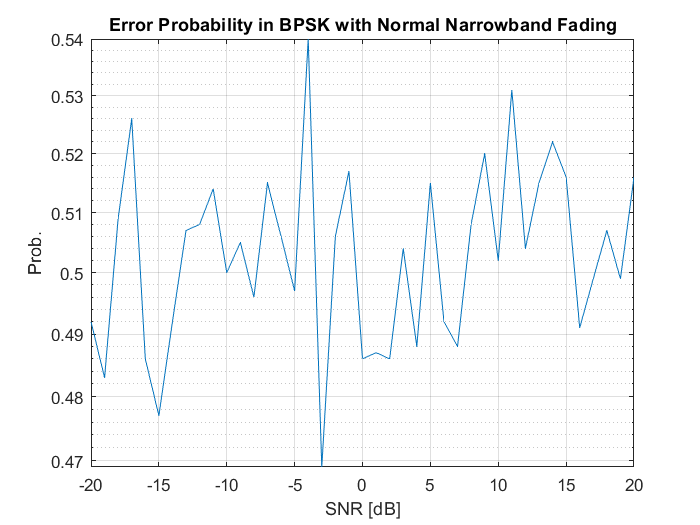

a = 1;
num_experiment = 1000;
x = randi([0 1],num_experiment,1);
x(x==0) = -a;
x(x==1) = a;
SNR = -20:20;
Error_1_1 = zeros(length(SNR),1);
for m=1:length(SNR)
    snr = SNR(m);
    N0 = a^2/(10^(snr/10));
    n = sqrt(N0) *(1/sqrt(2) * randn(num_experiment,1) + 1i/sqrt(2) *randn(num_experiment,1));
    h = 1/sqrt(2) * (randn(num_experiment,1)+1i*randn(num_experiment,1));
    y = h.*x + n;
    y_det = zeros(num_experiment,1);
    y_det(y>=0) = a;
    y_det(y<0) = -a;
    correct_det_num = sum(x==y_det);
    Error_1_1(m) = 1 - correct_det_num/num_experiment;
end
figure(1);
semilogy(SNR,Error_1_1);
xlabel('SNR [dB]');
ylabel('Prob.');
title("Error Probability in BPSK with Normal Narrowband Fading");
grid on;

ب

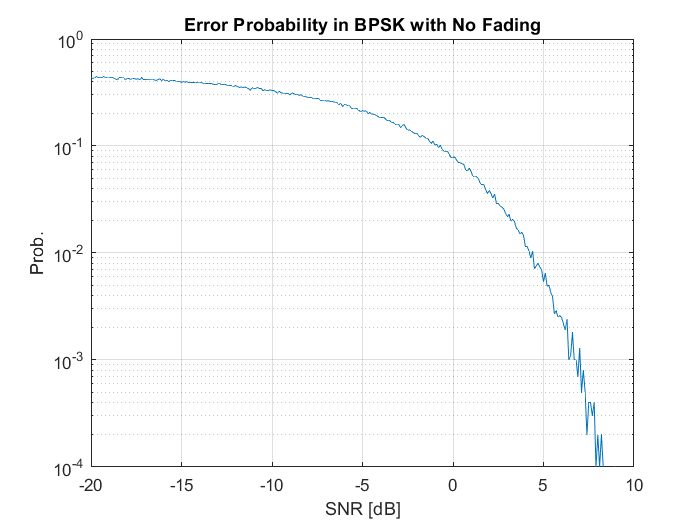

a = 1;
num_experiment = 10000;
x = randi([0 1],num_experiment,1);
x(x==0) = -a;
x(x==1) = a;
SNR = -20:0.1:20;
Error_1_2 = zeros(length(SNR),1);
for m=1:length(SNR)
    snr = SNR(m);
    N0 = a^2/(10^(snr/10));
    n = sqrt(N0) *(1/sqrt(2) * randn(num_experiment,1) + 1i/sqrt(2) * randn(num_experiment,1));
    y = x + n;
    y_det = zeros(num_experiment,1);
    y_det(y>=0) = a;
    y_det(y<0) = -a;
    correct_det_num = sum(x==y_det);
    Error_1_2(m) = 1 - correct_det_num/num_experiment;
end
figure(2);
semilogy(SNR,Error_1_2);
xlabel('SNR [dB]');
ylabel('Prob.');
title("Error Probability in BPSK with No Fading");
grid on;

## ***Q2***

الف

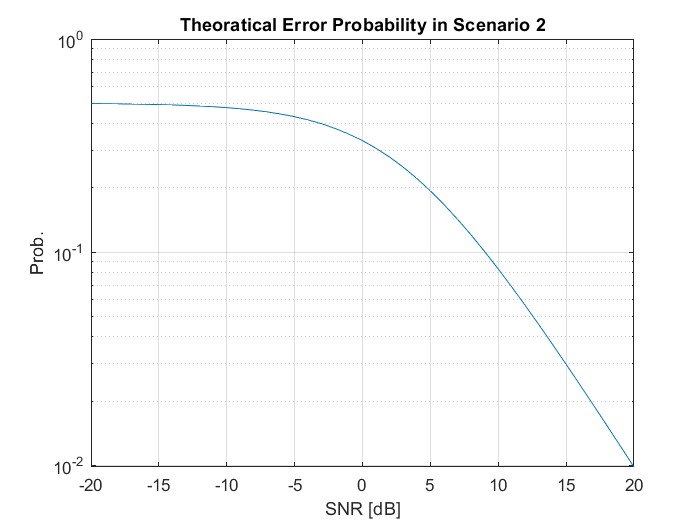

SNR = -20:20;
snr_lin = 10.^(SNR/10);
Pe_theory = 1./(2+snr_lin);
figure(3);
semilogy(SNR,Pe_theory);
xlabel('SNR [dB]');
ylabel('Prob.');
title("Theoratical Error Probability in Scenario 2");
grid on;

ب

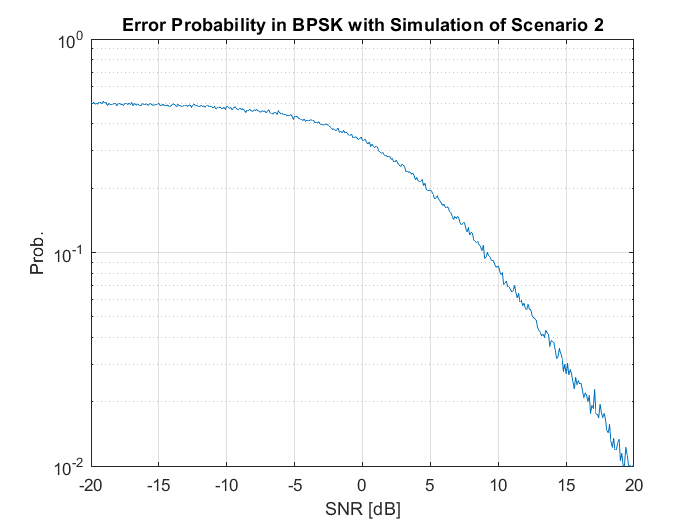

a = 1;
num_experiment = 10000;
x_tx = randi([0 1],num_experiment,1);
x_tx(x_tx==0) = -a;
x_tx(x_tx==1) = a;
x = zeros(2*num_experiment,1);
for i=1:num_experiment
    if x_tx(i) == a
        x(2*i-1) = 0;
        x(2*i) = a;
    else
        x(2*i-1) = -a;
        x(2*i) = 0;
    end
end
SNR = -20:0.1:20;
Error_2_1 = zeros(length(SNR),1);
for m=1:length(SNR)
    snr = SNR(m);
    N0 = a^2/(10^(snr/10));
    n = sqrt(N0) *(1/sqrt(2) * randn(2*num_experiment,1) + 1i/sqrt(2) *randn(2*num_experiment,1));
    h = 1/sqrt(2) * (randn(2*num_experiment,1)+1i*randn(2*num_experiment,1));
    y = h.*x + n;
    k_odd = 1:2:2*num_experiment;
    k_even = 2:2:2*num_experiment;
    y1 = y(k_odd);
    y2 = y(k_even);
    det_criteria = abs(y1)<abs(y2);
    y_det = zeros(num_experiment,1);
    y_det(det_criteria == 1) = a;
    y_det(det_criteria == 0) = -a;
    correct_det_num = sum(x_tx==y_det);
    Error_2_1(m) = 1 - correct_det_num/num_experiment;
end
figure(4);
semilogy(SNR,Error_2_1);
xlabel('SNR [dB]');
ylabel('Prob.');
title("Error Probability in BPSK with Simulation of Scenario 2");
grid on;

## ***Q3***

الف

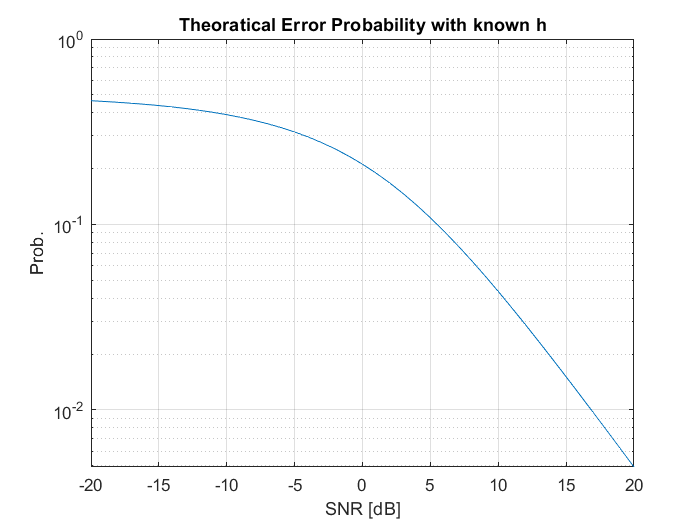

SNR = -20:20;
snr_lin = 10.^(SNR/10);
Pe_theory = 1/2 * (1 - sqrt(snr_lin./(2+snr_lin)));
figure(5);
semilogy(SNR,Pe_theory);
xlabel('SNR [dB]');
ylabel('Prob.');
title("Theoratical Error Probability with known h");
grid on;

ب

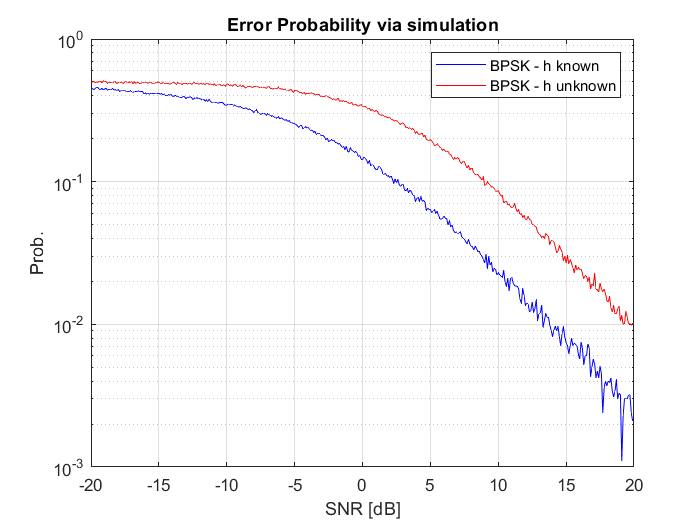

a = 1;
num_experiment = 10000;
x = randi([0 1],num_experiment,1);
x(x==0) = -a;
x(x==1) = a;
SNR = -20:0.1:20;
Error_3 = zeros(length(SNR),1);
for m=1:length(SNR)
    snr = SNR(m);
    N0 = a^2/(10^(snr/10));
    h = 1/sqrt(2) * (randn(num_experiment,1)+1i*randn(num_experiment,1));
    n = sqrt(N0) *(1/sqrt(2) * randn(num_experiment,1) + 1i/sqrt(2) * randn(num_experiment,1));
    y = h.*x+n;
    y = 1./h .* y;
    y_det = zeros(num_experiment,1);
    y_det(y>=0) = a;
    y_det(y<0) = -a;
    correct_det_num = sum(x==y_det);
    Error_3(m) = 1 - correct_det_num/num_experiment;
end
figure(6);
semilogy(SNR,Error_3,'b'); hold on;
semilogy(SNR,Error_2_1,'r');hold off;
legend('BPSK - h known','BPSK - h unknown');
xlabel('SNR [dB]');
ylabel('Prob.');
title("Error Probability via simulation");
grid on;

## ***Q4***

الف

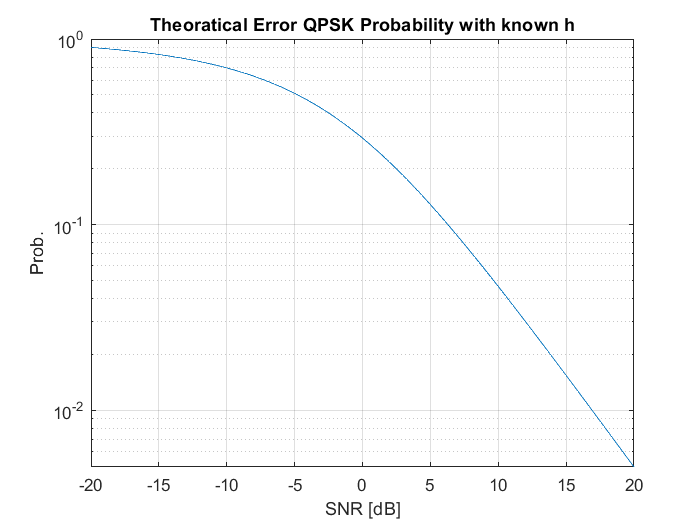

SNR = -20:0.1:20;
snr_lin = 10.^(SNR/10);
Pe_theory = (1 - sqrt(snr_lin./(1+snr_lin)));
figure(7);
semilogy(SNR,Pe_theory);
xlabel('SNR [dB]');
ylabel('Prob.');
title("Theoratical Error QPSK Probability with known h");
grid on;

ادامه الف

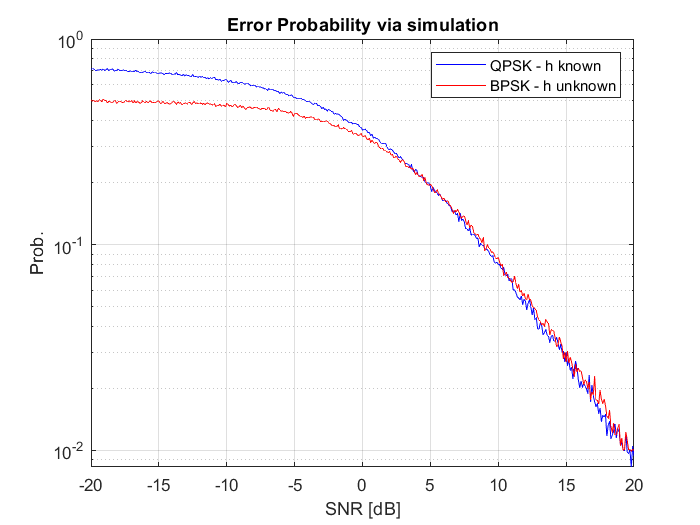

a = 1;
num_experiment = 10000;
x = randi([0 3],num_experiment,1);
transmitive_x = x;
x(x==0) = 1+1j;
x(x==1) = -1+1j;
x(x==2) = -1-1j;
x(x==3) = 1-1j;
x = 1/sqrt(2)*x;
SNR = -20:0.1:20;
Error_4 = zeros(length(SNR),1);
for m=1:length(SNR)
    snr = SNR(m);
    N0 = a^2/(10^(snr/10));
    h = 1/sqrt(2) * (randn(num_experiment,1)+1i*randn(num_experiment,1));
    n = sqrt(N0) *(1/sqrt(2) * randn(num_experiment,1) + 1i/sqrt(2) * randn(num_experiment,1));
    y_det = zeros(num_experiment,1);
    y = h.*x + n;
    y = 1./h .* y;
    y_det(real(y)>=0 & imag(y)>=0) = 0;
    y_det(real(y)<0 & imag(y)>=0) = 1;
    y_det(real(y)<0 & imag(y)<0) = 2;
    y_det(real(y)>=0 & imag(y)<0) = 3;
    correct_det_num = sum(transmitive_x==y_det);
    Error_4(m) = 1 - correct_det_num/num_experiment;
end
figure(8);
semilogy(SNR,Error_4,'b'); hold on;
semilogy(SNR,Error_2_1,'r');hold off;
legend('QPSK - h known','BPSK - h unknown');
xlabel('SNR [dB]');
ylabel('Prob.');
title("Error Probability via simulation");
grid on;

## ***Q5***

***ب 1***

% SNR = -20:0.1:20;
% snr_lin = 10.^(SNR/10);
% Pe_theory = (qfunc(sqrt(3/2*snr_lin)));
% figure(9);
% semilogy(SNR,Pe_theory);
% xlabel('SNR [dB]');
% ylabel('Prob.');
% title("Theoratical Error BPSK Diversity Probability with known h");
% grid on;

***ب 2***

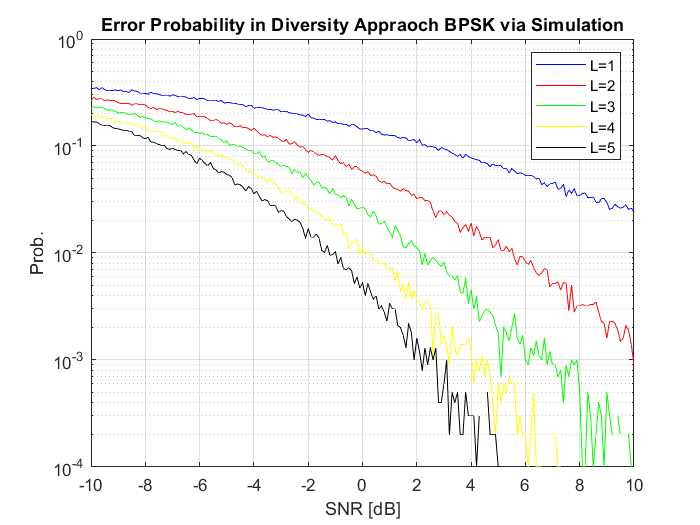

a = 1;
num_experiment = 10000;
x = randi([0 1],num_experiment,1);
x(x==0) = -a;
x(x==1) = a;
SNR = -10:0.1:10;
L_vals = [1 2 3 4 5];
Error_5 = zeros(length(SNR),length(L_vals));
for m =1:length(SNR)
    snr = SNR(m);
    N0 = a^2/(10^(snr/10));
    for k=1:length(L_vals)
        L = L_vals(k);
        h = 1/sqrt(2) * (randn(num_experiment,L)+1i*randn(num_experiment,L));
        n = sqrt(N0) *(1/sqrt(2) * randn(num_experiment,L) + 1i/sqrt(2) * randn(num_experiment,L));
        alpha = sqrt(abs(h).^2/N0);
        theta = angle(h);
        Z = alpha.*abs(h).*x + alpha.*exp(1i*theta).*n;
        z = sum(Z,2);
        y = real(z);
        y_det = zeros(num_experiment,1);
        y_det(y>=0) = a;
        y_det(y<0) = -a;
        correct_det_num = sum(x==y_det);
        Error_5(m,k) = 1 - correct_det_num/num_experiment;
    end
end
figure(10);
semilogy(SNR,Error_5(:,1),'b');hold on;
semilogy(SNR,Error_5(:,2),'r');
semilogy(SNR,Error_5(:,3),'g');
semilogy(SNR,Error_5(:,4),'y');
semilogy(SNR,Error_5(:,5),'black');hold off;
grid on;
legend('L=1','L=2','L=3','L=4','L=5');
xlabel('SNR [dB]');
ylabel('Prob.');
title("Error Probability in Diversity Appraoch BPSK via Simulation");

## ***Q6***

***ب***

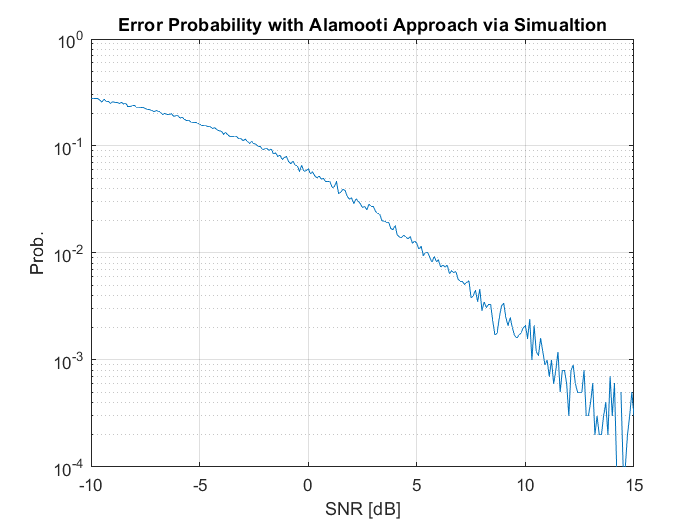

M = 2;
a = 1;
num_experiment = 10000;
x = randi([0 1],num_experiment,1);
x(x==0) = -a;
x(x==1) = a;
SNR = -10:0.1:15;
Error_6 = zeros(length(SNR),1);
for m=1:length(SNR)
    snr = SNR(m);
    N0 = a^2/(10^(snr/10));
    y_det = zeros(num_experiment,1);
    for i=1:num_experiment/2
        s_hat = zeros(M,1);
        h = 1/sqrt(2) * (randn(M,1)+1i*randn(M,1)); 
        n = sqrt(N0) *(1/sqrt(2) * randn(M,1) + 1i/sqrt(2) * randn(M,1));
        n(2) = conj(n(2));
        s = [x(2*i-1);x(2*i)];
        Hc = [h(1) h(2);conj(h(2)) -conj(h(1))];
        y = Hc*s+n;
        z = Hc'*y;
        s_hat(z>=0) = a;
        s_hat(z<0) = -a;
        y_det(2*i-1) = s_hat(1);
        y_det(2*i) = s_hat(2);
    end
    correct_det_num = sum(x==y_det);
    Error_6(m) = 1 - correct_det_num/num_experiment;
end
figure(11);
semilogy(SNR,Error_6);
grid on;
xlabel('SNR [dB]');
ylabel('Prob.');
title('Error Probability with Alamooti Approach via Simualtion');

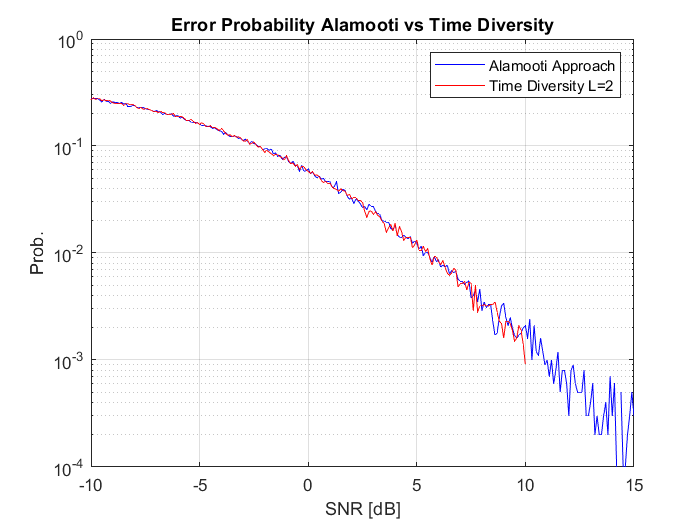

figure(12);
semilogy(SNR,Error_6,'b'); hold on;
semilogy(-10:0.1:10,Error_5(:,2),'r'); hold off;
legend("Alamooti Approach","Time Diversity L=2");
grid on;
xlabel('SNR [dB]');
ylabel('Prob.');
title('Error Probability Alamooti vs Time Diversity');